# Euler-Bernoulli Beam

## 一、问题概述

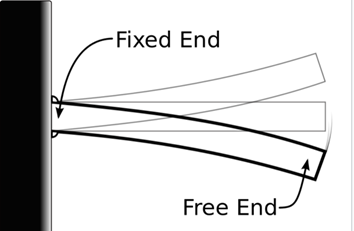

长度为$L$的欧拉梁，一端固支，解其挠度：${\textrm{EIy}}^{\prime \prime \prime \prime } \left(x\right)=f\left(x\right)$。对该微分方程离散后，可以得到一个线性方程组。

边界条件：$\begin{array}{l}
y\left(0\right)=y^{\prime } \left(0\right)=0\\
y^{\prime \prime \prime } \left(L\right)=y^{\prime \prime \prime \prime } \left(L\right)=0
\end{array}$

本例将给我们提供一个科学计算中的病态方程组求解的实例研究。

输入n和f(x)$\Rightarrow$高斯消元/雅可比/高斯-赛德尔/SOR$\Rightarrow$（返回）flag；结果；运行时间

## 二、参数设置

E = 1.3e10;
rho = 480;
g = 9.8;

L = 2;  % 跳水板长度
w = 0.3; % 跳水版宽度
d = 0.03; % 跳水板厚度
I = w*d^3/12 % 惯性模量

I = 6.7500e-07


f = -rho*w*d*g; %单位长度板的重力


$$I=\frac{{\textrm{wd}}^3 }{12}$$


三、生成系统矩阵$A$（见附录：）

N = 10*2.^(1:11);
result(length(N)).n = 0;

parfor i = 1:length(N)
    n = N(i); % 生成
    result(i).n = n;
    
    result(i).x = L/N(i)*(1:N(i)); % 离散点的坐标:x
    b0 = f*ones(N(i),1); % 跳板重力
    b1 = zeros(N(i),1); 
    b1(result(i).x>=1.8 & result(i).x<=2) = f; % 在跳板末端施加重量
    result(i).b = b0+b1; % 线性方程组的右端b
    
    b3 = [-1/4 zeros(1,n-4)];
    b2 = [8/3 ones(1,n-3)];
    b1 = [-9 -4*ones(1,n-3) -28/17];
    b = [16 6*ones(1,n-3) 72/17 72/17];
    b_1 = [-4*ones(1,n-3) -60/17 -156/17];
    b_2 = [ones(1,n-4) 16/17 96/17];
    b_3 = [zeros(1,n-4) -12/17];
    
    result(i).A = diag(b3,3) + diag(b2,2) + diag(b1,1) + diag(b) ...
        + diag(b_1,-1) + diag(b_2,-2) + diag(b_3,-3);
    if i>1000
        result(i).A = sparse(result(i).A)
    end
    
    result(i).cond = cond(result(i).A)
end

历时 0.009177 秒。
历时 0.003284 秒。
历时 0.010625 秒。
历时 0.061656 秒。
历时 0.022601 秒。
历时 0.148297 秒。
历时 1.103414 秒。
历时 0.430462 秒。
历时 0.007769 秒。
历时 13.452778 秒。
历时 5.196509 秒。


result(3).A

ans =    16.0000   -9.0000    2.6667   -0.2500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -4.0000    6.0000   -4.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

cond(ans)

ans = 6.9191e+07

四、实现高斯消元法（见附录：）

五、在n=10的条件下，求解没有负荷时的情况。比较不同方法的计算精度和计算速度，并进行必要的分析

六、比较不同网格大小时，高斯消元法的精度，并借助系统矩阵$A$的分析，分析误差随$n$变化的原因

七、在跳板末端加上$70\textrm{kg}$的跳水员，在不同网格大小下，对板的变形进行求解。找出最优的$n$，并画图找出跳水板在自由端的偏斜度

## 附录：函数